# Lab 4

## PART 1

#### Simulation for $\omega$= 1 rad/s

#### Simulation for $\omega$= 0.1 rad/s

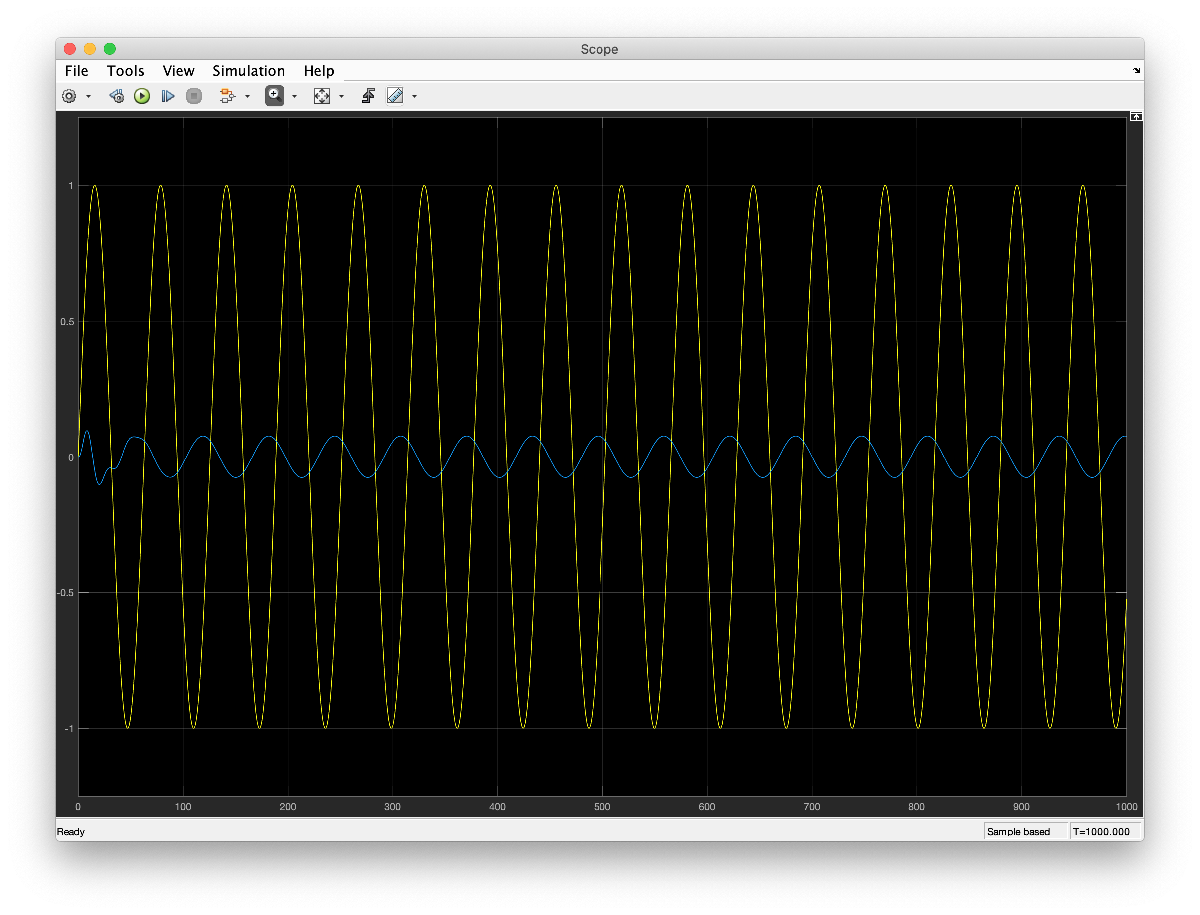

## PART 2 


% Define parameters
a=1; b=9; c=0.1; d=1; 

%Defien matrices 
A = [0, 1/b, 0, 0;
    -1/a, 0, 0, -1/a;
    0, 0, 0, 1/d;
    0, 1/b, -1/b, -1/(b*c)]

A =                    0   0.111111111111111                   0                   0
  -1.000000000000000                   0                   0  -1.000000000000000
                   0                   0                   0   1.000000000000000
                   0   0.111111111111111  -0.111111111111111  -1.111111111111111


B = [0;1/a;0;0]

B =      0
     1
     0
     0


C = [0, 0, 0, 1]

C =      0     0     0     1


D = 0

D =      0


[num,den] = ss2tf(A, B, C, D)

num =                    0                   0   0.111111111111111                   0                   0


den =    1.000000000000000   1.111111111111112   0.333333333333334   0.123456790123457   0.012345679012346


% Poles 
p = roots(den)

p =  -0.872677996249965 + 0.000000000000000i
 -0.055555555555556 + 0.328671099061090i
 -0.055555555555556 - 0.328671099061090i
 -0.127322003750035 + 0.000000000000000i


% Zeros
z = roots(num)

z =      0
     0


% Estimating the time required to reach steady-state. 
% Remember that T_s = 4.6/\sigma
% We use the dominant pole, which is p(2) or p(3)

Ts = 4.6/(abs(real(p(3))))

Ts =   82.799999999999571


#### Step responses. 

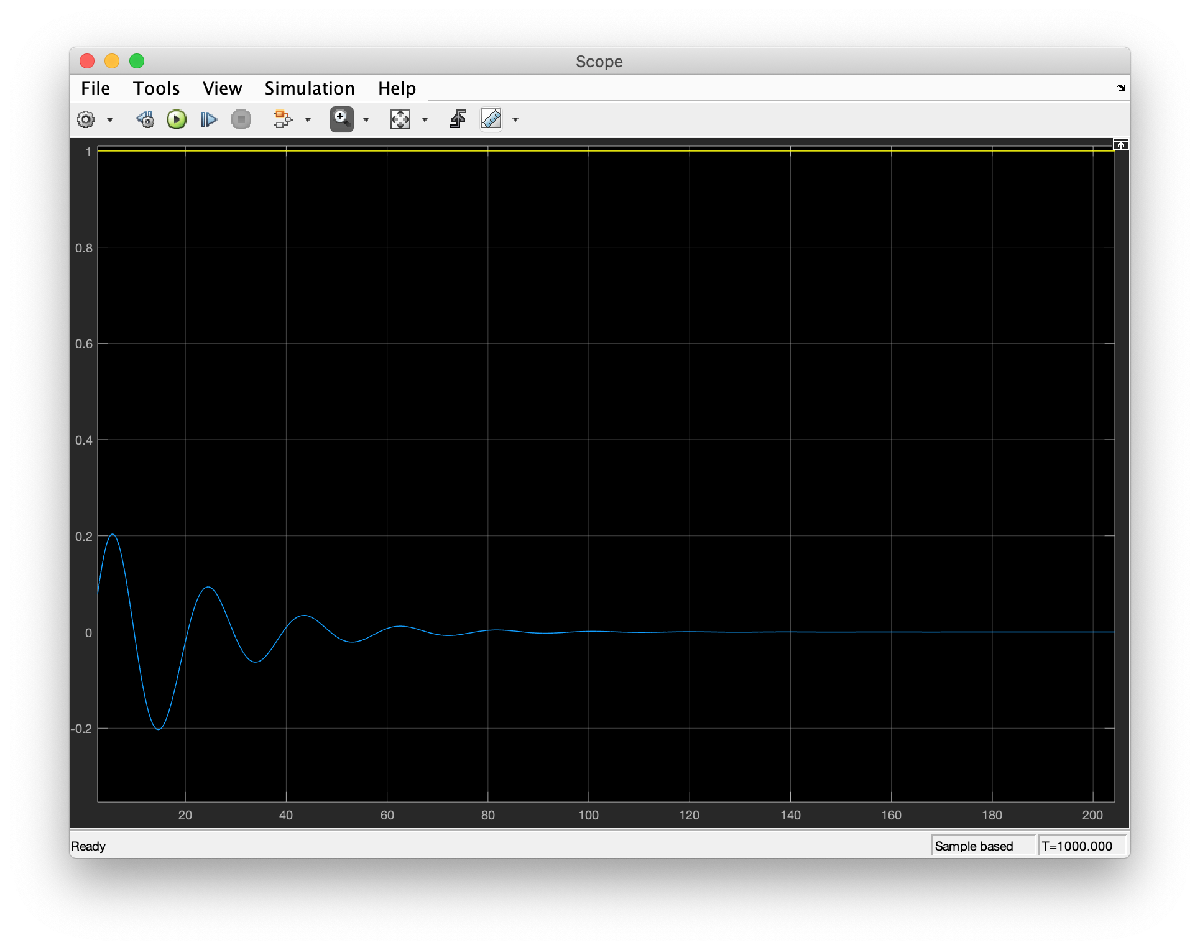

It is clear that $T_s$ = 82 seconds.  

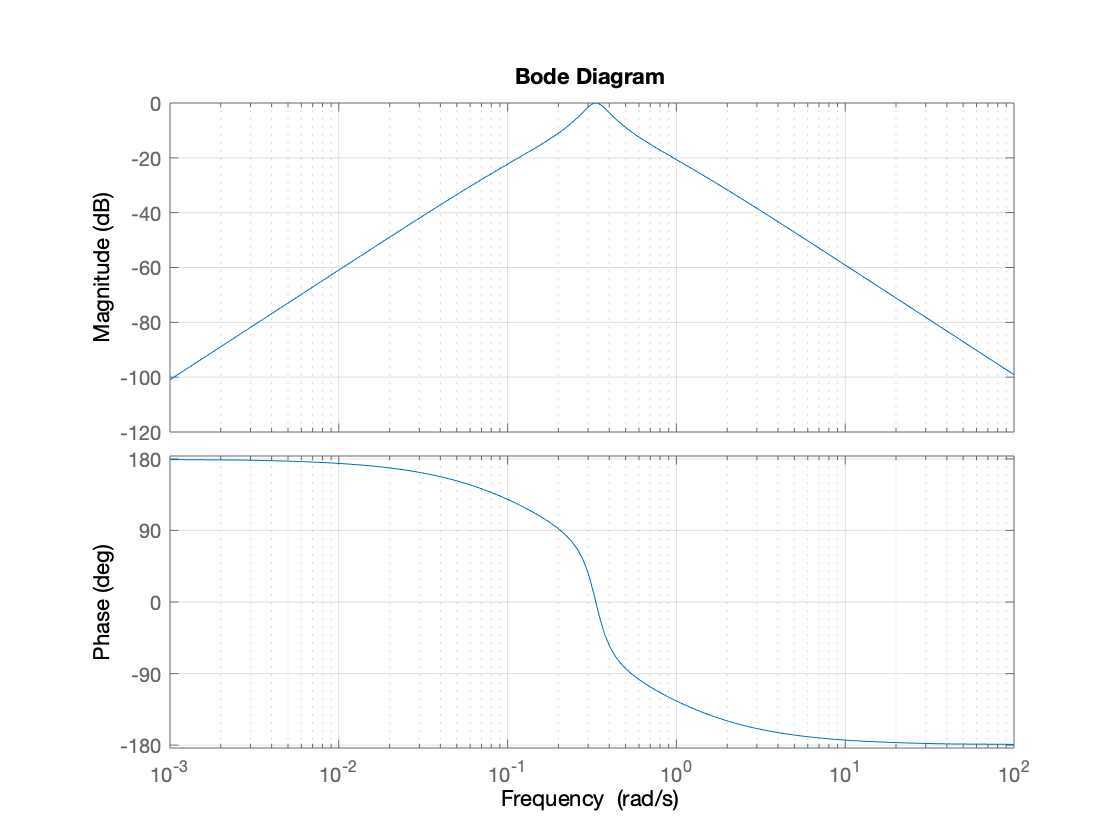

% Bode Plots 
bode(num, den); grid on;

[mag, phase, out] = bode(num,den); 
% Find index of maximum gain 
indx = find(mag == max(mag))

indx = 41

% Find frequency of maximum gain
freq_max = out(indx)

freq_max = 0.3385

% Find phase of maximum gain
phi_bode = phase(indx)

phi_bode = -5.8254

% Compute phase from simulation 
% dt = 301.574 ms 
% dt is computed from the steady-space cursor measurements 
% phi = (omega*dt)*180/pi
phi_sim = freq_max*(-301.574*1e-3);
phi_sim = phi_sim*180/pi

phi_sim = -5.8484

% Phi_bode & phi_max are almost equal.